## Cvičení 4 - soustavy rovnic:

Příklad:

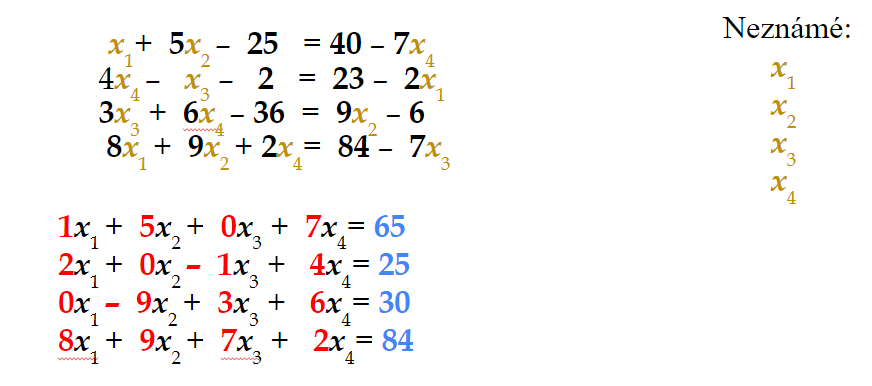

A = [1 5 0 7;2 0 -1 4;0 -9 3 6;8 9 7 2];
b = [65;25;30;84];
reseni_linearnich_rovnic(A,b)

ans =      1
     3
     5
     7


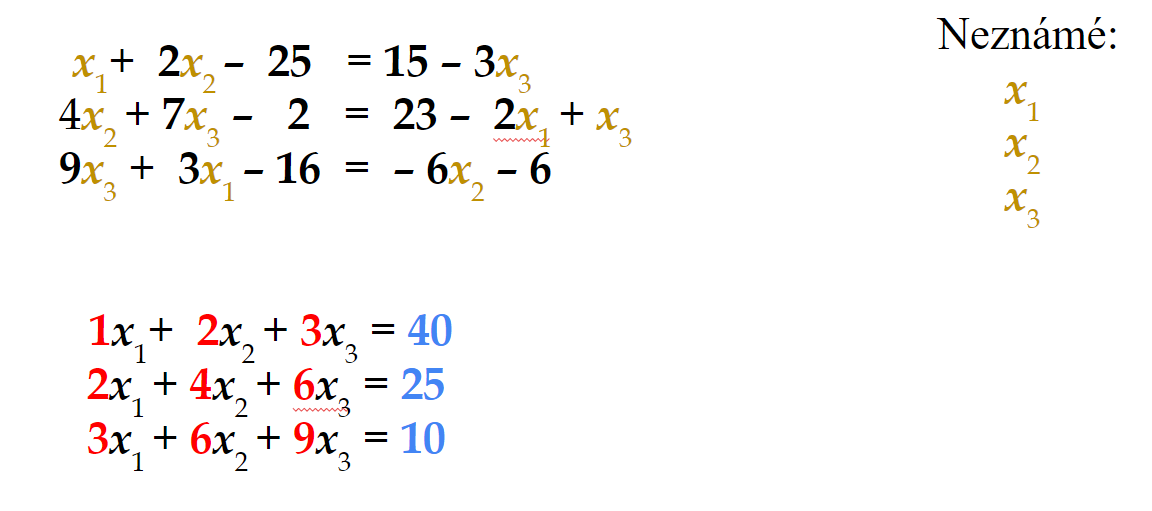

A = [1 2 3;2 4 6;3 6 9];
b = [40 25 10];
% reseni_linearnich_rovnic(A,b)

Slovní úlohy:

Maminka koupila k večeři jednu hovězí konzervu a tři paštiky. Zaplatila celkem 47 Kč. Jiná paní zaplatila za dvě konzervy a čtyři paštiky 82 Kč. Kolik stojí hovězí konzerva a kolik paštika?

% 1h + 3p = 47
% 2h + 4p = 82

reseni_linearnich_rovnic([1 3; 2 4],[47;82])

ans =     29
     6


*Turisté jsou ubytováni ve třech hotelích. V druhém hotelu je ubytovaných o 8 turistů více než v prvním a ve třetím o 14 více než v druhém. Kolik turistů bydlí v každém hotelu, pokud jich je spolu 258?*

% b = 8 + a
% c = 14 + b
% a + b + c = 258

A = [-1 1 0;0 -1 1; 1 1 1];
b = [8;14;258];

reseni_linearnich_rovnic(A,b)	

ans =     76
    84
    98


Řešení soustavy lineárních rovnic:


$$\begin{array}{l}
a_{11} x_1 \;+a_{12} x_2 =b_1 \\
a_{21} x_1 \;+a_{22} x_2 =b_2 
\end{array}$$



$$\mathit{\mathbf{A}}*\mathit{\mathbf{x}}\;=\mathit{\mathbf{b}}\;$$
                  

$b=\left\lbrack \begin{array}{c}
b_1 \\
b_2 
\end{array}\right\rbrack$,        $x=\left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack$,         $A=\left\lbrack \begin{array}{cc}
a_{11}  & a_{12} \\
a_{21}  & a_{22} 
\end{array}\right\rbrack$


$$\mathit{\mathbf{A}}*\mathit{\mathbf{x}}\;=\mathit{\mathbf{b}}\;=\left\lbrack \begin{array}{cc}
a_{11}  & a_{12} \\
a_{21}  & a_{22} 
\end{array}\right\rbrack *\left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
b_1 \\
b_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
a_{11} x_1  & a_{12} x_2 \\
a_{21} x_1  & a_{22} x_2 
\end{array}\right\rbrack$$



$$\mathit{\mathbf{x}}\;={\mathit{\mathbf{A}}}^{-1} *\mathit{\mathbf{b}}$$


function [x] = reseni_linearnich_rovnic(A,b)
% pokud je determinant rovno nule, je matice singulární a nelze vyřešit (chceme aby byla naopak regulární)
% if det(A) ~= 0 
if abs(det(A)) > 1e-12 
   x = A\b;
else
    disp("Determinant matice: ") % Nesmí být nula, nebo se nule blížit
    disp(det(A));
    disp("Podminennost matice: ") % Definuje jak moc dobře se dá s maticí počítat
    disp(cond(A));
    error('Soustava nema reseni!')    
end
end